 %  Copyright 2021 University of Padua, Italy
 %
 %  Licensed under the Apache License, Version 2.0 (the "License");
 %  you may not use this file except in compliance with the License.
 %  You may obtain a copy of the License at
 %
 %       http://www.apache.org/licenses/LICENSE-2.0
 %
 %  Unless required by applicable law or agreed to in writing, software
 %  distributed under the License is distributed on an "AS IS" BASIS,
 %  WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied.
 %  See the License for the specific language governing permissions and
 %  limitations under the License.
 %
 % 
 % @author Nicola Ferro

# Computation of one-way ANOVA on TREC 08, 1999, AdHoc

This example shows how to compare runs from TREC 08, 1999, AdHoc using one-way ANOVA.

## Setup

Load the performance score about the runs. The file contains:

- `ap` (or another measure name): a matrix where rows are topics and columns are runs; each cell contains the AP score for a run on a given topic;

- `runs`: an array of strings containing the identifiers of the runs; elements in the array are in the same order as columns on ap;

- `topics`: an array of strings containing the identifiers of the topics; elements in the array are in the same order as rows on ap;

% Load Average Precision data
% Other measures available are: P@10, nDCG, RBP
load C:\Users\Andrea\Desktop\MAGISTRALE\Anno1-sem2\SearchEngines\HWS\seupd2021-goldr\RUN\RUN2020\RunAnalysis\runtotonlyprec20.mat
% rename ap into measure to make follow-up processing the same for whatever
% measure we load
measure_prec20 = runtotonlyprec20(1:49,:);
measure_prec20 = table2array(measure_prec20)

measure_prec20 =     0.4000    0.4000    0.4000    0.4000    0.3500
    0.2000    0.2000    0.2000    0.2000    0.1500
    0.2000    0.2000    0.2000    0.1500    0.1500
    0.3000    0.3000    0.3000    0.3500    0.2500
    0.2000    0.2000    0.2000    0.1000    0.1000
    0.3000    0.2500    0.3000    0.2000    0.1000
    0.3500    0.3500    0.3500    0.2500    0.1500
    0.2500    0.2500    0.2000    0.0500         0
    0.3500    0.4000    0.3500    0.3500    0.1500
    0.2500    0.3500    0.2500    0.2500    0.2000



% remove the now useless ap matrix
clear runtotonlyprec20;

% the significance level
alpha = 0.05;

Reorder the measure by mean performance

% the mean for each run across the topics
% Note that if the measure is AP (Average Precision), 
% this is exactly MAP (Mean Average Precision) for each run
m_avg_prec20 = mean(measure_prec20);

myruns_prec20 = ogmyruns

myruns_prec20 = 1×5 string array
    "run1"    "run2"    "run3"    "run4"    "run5"


% sort in descending order of mean score
[~, idx] = sort(m_avg_prec20, 'descend');

% re-order runs by descending mean of the measure
measure_prec20 = measure_prec20(:, idx);
myruns_prec20 = myruns_prec20(idx);

## One-way ANOVA

Compute the one-way ANOVA

% perform the ANOVA
[~, tbl_prec20, sts_prec20] = anova1(measure_prec20, myruns_prec20, 'off');

% display the ANOVA table
tbl_prec20

tbl_prec20 = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[0.4927]}    {[  4]}    {[  0.1232]}    {[  9.5435]}    {[3.5446e-07]}
    {'Error'  }    {[3.0976]}    {[240]}    {[  0.0129]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[3.5902]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }


Perform the multiple comparison

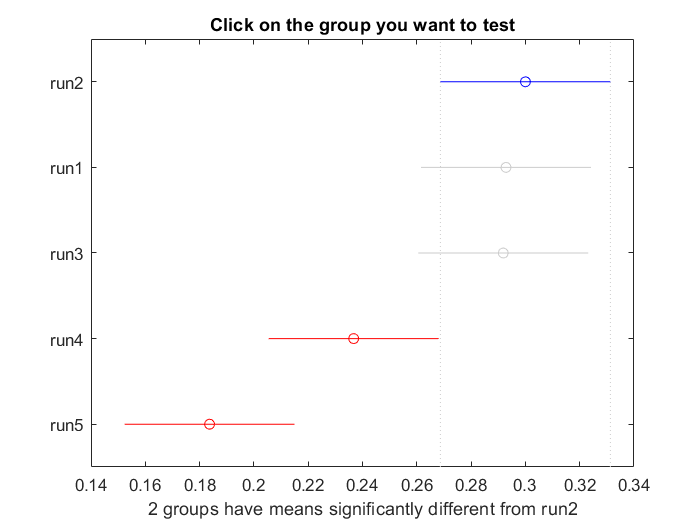

c = multcompare(sts_prec20, 'Alpha', alpha, 'Ctype', 'hsd'); 


% display the multiple comparisons
c

c =     1.0000    2.0000   -0.0555    0.0071    0.0698    0.9980
    1.0000    3.0000   -0.0544    0.0082    0.0708    0.9966
    1.0000    4.0000    0.0007    0.0633    0.1259    0.0462
    1.0000    5.0000    0.0537    0.1163    0.1789    0.0000
    2.0000    3.0000   -0.0616    0.0010    0.0636    1.0000
    2.0000    4.0000   -0.0065    0.0561    0.1187    0.1035
    2.0000    5.0000    0.0466    0.1092    0.1718    0.0000
    3.0000    4.0000   -0.0075    0.0551    0.1177    0.1150
    3.0000    5.0000    0.0456    0.1082    0.1708    0.0000
    4.0000    5.0000   -0.0095    0.0531    0.1157    0.1410


## Two-way ANOVA - da finire

Compute the two-way ANOVA

% perform the ANOVA
[~, tbl2_prec20, sts2_prec20] = anova2(measure_prec20, 1,'off');

% display the ANOVA table
tbl2_prec20

tbl2_prec20 = 5×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[0.4927]}    {[  4]}    {[  0.1232]}    {[ 44.4280]}    {[2.2670e-26]}
    {'Rows'   }    {[2.5652]}    {[ 48]}    {[  0.0534]}    {[ 19.2765]}    {[1.1206e-51]}
    {'Error'  }    {[0.5323]}    {[192]}    {[  0.0028]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[3.5902]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }



% display the ANOVA table
tbl2_prec20

tbl2_prec20 = 5×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[0.4927]}    {[  4]}    {[  0.1232]}    {[ 44.4280]}    {[2.2670e-26]}
    {'Rows'   }    {[2.5652]}    {[ 48]}    {[  0.0534]}    {[ 19.2765]}    {[1.1206e-51]}
    {'Error'  }    {[0.5323]}    {[192]}    {[  0.0028]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[3.5902]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }


Perform the multiple comparison

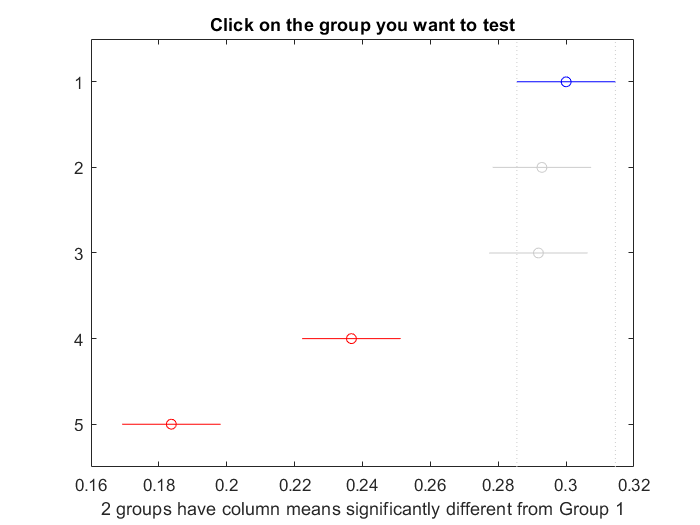

c2 = multcompare(sts2_prec20, 'Alpha', alpha, 'Ctype', 'hsd'); 

c2

c2 =     1.0000    2.0000   -0.0219    0.0071    0.0362    0.9626
    1.0000    3.0000   -0.0209    0.0082    0.0372    0.9400
    1.0000    4.0000    0.0342    0.0633    0.0923    0.0000
    1.0000    5.0000    0.0873    0.1163    0.1453    0.0000
    2.0000    3.0000   -0.0280    0.0010    0.0300    1.0000
    2.0000    4.0000    0.0271    0.0561    0.0851    0.0000
    2.0000    5.0000    0.0802    0.1092    0.1382    0.0000
    3.0000    4.0000    0.0261    0.0551    0.0841    0.0000
    3.0000    5.0000    0.0791    0.1082    0.1372    0.0000
    4.0000    5.0000    0.0240    0.0531    0.0821    0.0000
